# Predicting Building Energy Consumption

## Introduction

This hackathon focuses on mitigating climate change, as you are tasked with training a model that predicts building energy consumption based on regional differences in building energy efficiency. Work like this can help determine which buildings are using and maybe *wasting *the most energy, which could be great candidates for retrofitting. Since the model will be predicting a building's energy consumption, which is a quantitative result, this problem could be solved using a regression model. Learn more about and download the challenge dataset by registering for [this Kaggle competition](https://www.kaggle.com/competitions/widsdatathon2022/data) and downloading the training dataset, called 'train.csv'. 

This tutorial uses an example dataset to show you how to complete the steps of building your own regression model, so **make sure to replace this dataset with the challenge dataset before making your own models. **

## Access and Explore the Data 

Real-world data tends to come with real-world challenges. Datasets could be stored in a variety of different file types, may be stored across several files, and can get messy and confusing. In this section, I will discuss some basic steps for loading and cleaning up a dataset in MATLAB®.

### Step 1: Import Your Data

In order to start working with data, you have to first bring it into the Workspace. Since the dataset is stored in one .CSV file, I will be importing the data as a table. Tables can store data with different data types and allow for the use of headers to label the data in a column, also called a *variable*, so they lend themselves nicely for storing large or complicated datasets in the workspace. 

The [`readtable`](https://www.mathworks.com/help/releases/R2024b/matlab/ref/readtable.html) function allows you to import data from the .CSV file as a table

train = readtable('exampleTrain.csv');

## Preprocess the Data

Now that you have the data in the Workspace, it is time to prepare it for machine learning. It is important that the data is in the correct format and that the values are what you expect them to be, as this can prevent error messages and poor model performance later on in the workflow. 

### Step 2: Clean Data

Datasets may be missing entries, they may have thousands of rows or *observations*, they could utilize a variety of data types, the measurements may not have been taken in perfect conditions, and the data collected may not be equally representative of all possible inputs. Before you can create a model, it is important to clean the data up so that it accurately reflects the problem and can easily be used as input to train the model. 

There are many different approaches you can take to work with missing values and inconsistent data. I will go through some basic steps in this post, but you can also refer to this [documentation page](https://www.mathworks.com/help/matlab/matlab_prog/clean-messy-and-missing-data-in-tables.html) to learn more.

First, I use the 'summary' function to learn more about the data types and get basic statistics about the data for each variable. 

summary(train)


train: 75757×64 table

Variables:

    Var1: cell array of character vectors
    Var2: double
    Var3: double
    Var4: cell array of character vectors
    Var5: double
    Var6: cell array of character vectors
    Var7: cell array of character vectors
    Var8: double
    Var9: double
    Var10: double
    Var11: double
    Var12: double
    Var13: double
    Var14: double
    Var15: double
    Var16: double
    Var17: cell array of character vectors
    Var18: double
    Var19: double
    Var20: cell array of character vectors
    Var21: cell array of character vectors
    Var22: double
    

Once you have learned more about the data, you can begin to think of ways to clean it up. 

#### *Remove Incompatible Variables*

Some algorithms that can be used to train regression models only allow for numeric values, so let's remove any non-numeric variables. Those are imported as cell arrays, so check which columns are of type 'cell' and remove them.

columnDataTypes = varfun(@iscell, train, OutputFormat="cell");
nonNumericCols = cell2mat(columnDataTypes);
nonNumColNames = train.Properties.VariableNames(nonNumericCols);

train = removevars(train, nonNumColNames)

train = 75757×50 table
     Var2        Var3       Var5       Var8      Var9     Var10      Var11    Var12    Var13     Var14      Var15    Var16    Var18      Var19      Var22     Var23    Var24     Var25    Var26      Var27      Var28     Var30      Var31      Var32     Var34     Var35       Var36     Var37    Var39     Var41     Var43       Var44       Var45      Var46     Var47       Var48<

#### *Handle Missing Data*

With some datasets, there may be a good way to approximate the value of a missing entry, and if you do not have a lot of data to work with, it may be important to try to fill in these gaps. In MATLAB, the easiest way to fill missing entries is to use the [`fillmissing`](https://www.mathworks.com/help/matlab/ref/fillmissing.html) function. It allows you to easily approximate and fill in missing values by indicating how you would like the values to be filled. 

While there are certainly benefits to filling in missing values, doing so can get complicated and may result in poor performance of the model if the approximations are not representative of the actual data. Since our dataset is very large, I'll just remove any variables with missing data. 

% Get indices of all missing values
missingIdx = ismissing(train);

% Get indices of any rows that contain missing values
rowIdxWithMissing = any(missingIdx, 2);

% Show how many are missing from each column
numMissingByCol = sum(missingIdx)

numMissingByCol =            0           0           0           0           0         884           0           0           0           0           0        2302           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        1998           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0       21707           0           0           0


This table shows that some columns are missing quite a few of their entries. Lets check what columns these are.

colsWithMissing = train.Properties.VariableNames(find(numMissingByCol))

colsWithMissing = 1×4 cell array
    {'Var10'}    {'Var16'}    {'Var41'}    {'Var60'}


Since we have a lot of variables, I'll just remove these.

train = removevars(train, colsWithMissing)

train = 75757×46 table
     Var2        Var3       Var5       Var8      Var9    Var11    Var12    Var13     Var14      Var15    Var18      Var19      Var22     Var23    Var24     Var25    Var26      Var27      Var28     Var30      Var31      Var32     Var34     Var35       Var36     Var37    Var39     Var43       Var44       Var45      Var46     Var47       Var48      Var49    Var50    Var51

#### *Separate the Predictor*

Since 'OutputVar' is our predictor variable, I will move this to its own variable, which makes it easier to manipulate the dataset for the rest of the preprocessing steps. 

actualOutput = train.OutputVar;
train = removevars(train, "OutputVar")

train = 75757×45 table
     Var2        Var3       Var5       Var8      Var9    Var11    Var12    Var13     Var14      Var15    Var18      Var19      Var22     Var23    Var24     Var25    Var26      Var27      Var28     Var30      Var31      Var32     Var34     Var35       Var36     Var37    Var39     Var43       Var44       Var45      Var46     Var47       Var48      Var49    Var50    Var51

#### *Normalize the Data*

Each column in most datasets contain measurements taken at different units, which is why we see a mix of very small and very large numbers, integers and floating-point numbers, and even text. This makes it difficult to create a machine learning algorithm that can account for the great variance between variables. Normalizing scales numeric data so the columns are within a similar range, which makes it easier for the algorithms to "understand" which measurements are small and which ones are big, and can lead to a faster and more accurate model. You can use the Normalize Data live task to normalize the entire dataset before training. 

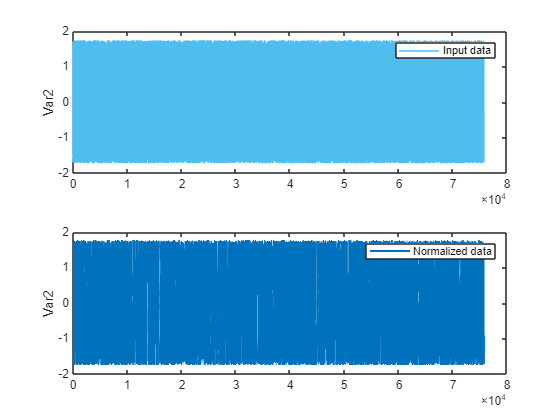

% Normalize Data
train = normalize(train);

% Display results
figure
tiledlayout(2,1);
nexttile
plot(train.Var2,"SeriesIndex",6,"DisplayName","Input data")
legend
ylabel("Var2")

nexttile
plot(train.Var2,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Normalized data")
legend
ylabel("Var2")

set(gcf,"NextPlot","New")

### Step 3: Create Training and Testing Data

No matter what format your data is in, it is important to have separate training and testing data. Training data is fed to the model, which "teaches" the model how to predict the output value; the testing data is sent to the model after it has already been trained to see how well it performs on new data. Often, it is also beneficial to have validation data, which is used during training to prevent overfitting. 

Overfitting is when the model learns the training data so well that it is able to predict the output of the training data with a high level of accuracy, but performs poorly when predicting the output for any other data. 

#### *Separate the dataset*

When creating training and testing sets, it is important to try to ensure that both sets contain a variety of data. Here, we separate the data by a random partition, reserving 20% for testing. 

c = cvpartition(height(train), 'Holdout', 0.2);

idxTrain = training(c);
trainingData = train(idxTrain,:);
trainingOutput = actualOutput(idxTrain);

idxTest = test(c);
testingData = train(idxTest,:);
testingOutput = actualOutput(idxTest);

It is up to you to determine how you will split the data between training and testing.

## Train a Model

Now that the data has been prepared, it is time to start training a model! I will be showing how to use the [Regression Learner app](https://www.mathworks.com/help/stats/regression-learner-app.html) to create a model. Additionally, if you would like to watch a video overview of the Regression Learner app, you can find one for a different dataset [here](https://www.mathworks.com/videos/forecast-electrical-load-using-the-regression-learner-app-1536231842528.html)!

### Step 4: Train Models using the Regression Learner App

The Regression Learner App lets you interactively train, validate, and tune different regression models. Here is how you can get started:

**1. Open the App: **On the 'Apps' tab, in the 'Machine Learning and Deep Learning' section, click **Regression Learner**. 

Alternatively, you can open the Regression Learner app from the command line:

regressionLearner

**2. Start a New Session: **Click **New Session** and select your training data from the workspace, which is 'trainingData' in this example. Specify the response variable, which is a variable from the workspace named 'trainingOutput' for this example. 

**3. Choose a Validation Method: **Select the validation method you want to use to avoid overfitting. You should see three options: Cross-Validation, Holdout Validation, and Resubstitution Validation. For problems where you have a large amount of data to work with, you may wish to choose Holdout Validation. You can refer to this [documentation page](https://www.mathworks.com/help/stats/select-data-and-validation-for-regression-problem.html#bvi2d8a-13) to learn more about these validation methods. 

**4. **Click **Start Session**

**5. Investigate Variable-Response Relationships: **Use the response plot to investigate which variables are useful for predicting the response. To visualize the relationship between different variables and 'OutputVar', select different variables in the 'X' list under 'X-axis'. Observe which variables are correlated most clearly with the response. This can help you decide how you want to process your data in future iterations (because machine learning is an iterative process!)

**6. Select Model(s): **On the 'Regression Learner' tab, in the 'Model Type' section, select the algorithm(s) you want trained. You may want to start with **All Quick-To-Train** to compare a few different options.

**7. (Optional) Tune parameters: **The Regression Learner app enables users to specify certain preferences when training a model. The 'Options' section allows you to choose which variables are used to train the model or to enable principal component analysis (PCA). To learn more about the advanced options for each model type, please refer to this [documentation page](https://www.mathworks.com/help/stats/choose-regression-model-options.html).

**8. **Click **Train**.

**9. Investigate Model Performance: **Once the models have finished training and validation, the 'Models' window on the left displays the trained models and their root mean square error (RMSE). Notice that the lowest RMSE value is highlighted to indicate this. Please note: the numbers you see may be a little different. 

In addition to the RSMEs, you can measure the results of training by creating visuals through the 'Plots' section of the 'Regression Learner' tab. The 'Plots and Results' section of the drop down menu allows you to plot the relationships between predicted and actual values of 'OutputVar' for any trained model. Simply click on the model you want to evaluate, then click on the type of plot you want to see!

To learn more about assessing a model from within the app, please refer to this [documentation page](https://www.mathworks.com/help/stats/assess-model-performance-in-regression-learner.html).

### Step 5: Export your Model

Once you have tested different settings and found a model that performs well, export the model to the Workspace by selecting the model and clicking **Export Model** from the Regression Learner App. This will allow you to make predictions on the test set. I used the default name 'trainedModel' when exporting.  

As can be seen below, the exported model is actually a structure containing the model object as well as some additional information about the model, or *metadata*. 

trainedModel

trainedModel = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {1×45 cell}
          LinearModel: [1×1 LinearModel]
                About: 'This struct is a trained model exported from Regression Learner R2024b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replace 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


## Evaluate Your Model

Once you have a model in the Workspace, you should evaluate it against the test data to see how the model performs on data that it has not seen. There are many ways to evaluate a model's performance, and in this section I will show how to collect some numeric measurements of a model's performance, though you should consider incorporating visual evaluations in your final presentation. If you are interested in learning more about other functions that can aid in assessing a model's performance, please refer to the relevant 'Diagnostics' section within this [documentation page](https://www.mathworks.com/help/stats/model-building-and-assessment.html?searchHighlight=diagnostics&s_tid=srchtitle_diagnostics_7)

### **Step 6: Collect Measurements**

The following code returns the predicted responses to the new test data:

predicted = trainedModel.predictFcn(testingData);

If you created your model programmatically instead of through the Regression Learner app, then you would need to use the syntax below:

Using these predictions, we can take a look at the model's performance from a few different perspectives. First, it will be helpful to calculate the *error*, or the difference between the actual 'OutputVar' value and the predicted 'OutputVar', for each observation in the test set:

testErrors = testingOutput - predicted;

In many cases, the array of error values will be too large to read through every single entry, and even if we did, it would be difficult to draw any meaningful conclusions. A simple measure of error may be to determine the average error value:

testAvgError = sum(abs(testErrors)) ./ length(testingOutput)

Unfortunately, this does not tell us anything about the distribution of error, so it is not really representative of the performance of our model. Root mean squared error is a common metric in machine learning, as it is more representative of the performance of a model than the average error. You can learn more about [RMSE](https://www.mathworks.com/help/matlab/ref/rmse.html#mw_3242e694-a6dd-4e0b-af7d-e66d292e66bc) at this documentation page. 

rmseVals = rmse(predicted, testingOutput)

## Rinse & Repeat

There is no one algorithm that suits all problems. You should create and test many different models because there are so many ways to fine tune a model, and even two models that have similar RMSE may perform better on different parts of the data. When using the Regression Learner app, do not just go with the model that performs best initially, but try changing parameters on a bunch of them. Change the training data, the validation method, the advanced options, the model type, and anything else that you come up with! Even if the change does not result in better performance, you might be able to learn something from it. 

For each model you create, try asking yourself these questions:

- Does it perform better than my other models?

- What are the differences between this and my other models? What are the similarities?

- Which observations does it perform poorly on? Why? 

If you have exported a model to the workspace and you wish to save it for later use or comparison, you may want to give it a descriptive name and save it to a .MAT file. To save the model I made in this example, I execute the following:

firstMdl = trainedModel;
save firstMdl firstMdl;

This way if you clear your workspace or accidentally overwrite the 'trainedModel' variable, you still have the model saved. When you want to use it again, you can easily load it back into the workspace:

load firstMdl firstMdl;

## Further Examples

If you are interested in learning more about regression learning and other data science workflows in MATLAB, please refer to the following examples:

- This [Data Science Tutorial video series](https://www.mathworks.com/videos/series/data-science-tutorial.html) will take you through a more in-depth walk through of the regression learning process when the data is stored across multiple files. This is a great example if you have the time! You can find the code in the 'Related Resources' section of each video if you wish to follow along. 

- The [Machine Learning Onramp](https://www.mathworks.com/learn/tutorials/machine-learning-onramp.html?s_tid=srchtitle_machine%2520learning%2520onramp_1) brings you through a few classification examples and teaches the basics of machine learning with MATLAB. 

- Our [Deep Learning Onramp](https://www.mathworks.com/learn/tutorials/deep-learning-onramp.html?s_tid=srchtitle_machine%2520learning%2520onramp_3) walks you through introductory deep learning methods for creating networks in MATLAB for image recongition. 

- If you are interested in a more advanced regression example, this [Time Series Forecasting Using Deep Learning](https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html) page shows users how they can use a neural network to predict a future number of chickenpox cases. 

## Additional Resources

- [Overview of Supervised Learning (Video)](https://www.youtube.com/watch?v=VZw_Hi4LzDQ&t=35s)

- [Missing Data in MATLAB](https://www.mathworks.com/help/matlab/data_analysis/missing-data-in-matlab.html)

- [Supervised Learning Workflow and Algorithms](https://www.mathworks.com/help/stats/supervised-learning-machine-learning-workflow-and-algorithms.html)

- [Train Regression Models in Regression Learner App](https://www.mathworks.com/help/stats/train-regression-models-in-regression-learner-app.html)

- [Export Regression Model to Predict New Data](https://www.mathworks.com/help/stats/export-regression-model-to-predict-new-data.html)

- [8 MATLAB Cheat Sheets for Data Science](https://www.mathworks.com/campaigns/offers/data-science-cheat-sheets.html)

- For a basic introduction to MATLAB: [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html?s_tid=srchtitle_machine%2520learning%2520onramp_4)